clear;clc;close all
syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)
syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

H = Hs + He + Hi + Hr;
M = Ms + Me + Mi;

ode1 = diff(Ms) == lambda - beta_m * Hi * Ms/H - mu_m * Ms;
ode2 = diff(Me) == beta_m * Hi * Ms/H - (theta_m + mu_m) * Me;
ode3 = diff(Mi) == theta_m * Me - mu_m * Mi;
ode4 = diff(Hs) == - beta_h * Mi * Hs/M + (He + Hi + Hr) * mu_h;
ode5 = diff(He) == beta_h * Mi * Hs/M - (theta_h + mu_h) * He;
ode6 = diff(Hi) == theta_h * He - (gamma_h + mu_h) * Hi;
ode7 = diff(Hr) == gamma_h * Hi - mu_h * Hr;
ode8 = diff(Hit) == theta_h * He;

odes = [ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars = [Hit Hi Me Hr Hs He Ms Mi];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [17 17             %Hit0
          17 17             %Hi    
          0	100             %Me
          0 100             %Hr
          50000	250000      %Hs
          0	1000            %He
          0	120000          %Ms
          0	100             %Mi
         ];
     
Range2 = [0	4
          0	4
          0.4	1.8
          0	42694
          0.0004 0.0004
          0.01 0.6
          0.7	1.75
          0.58	0.88
        ];     

Range = [Range1; Range2];

ParNames = {'\lambda'; '\beta_m'; '\mu_m'; '\theta_m'; '\beta_h'; '\theta_h'; '\gamma_h'};
VarNames = {'M_e(0)'; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)'};

FullNames = [VarNames; ParNames];

Finally, use the gsua_dpmat to create the functional table

[T,~] = gsua_dpmat(odes,vars,[0 39],'Model','output',2,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Row = ["M_e(0)"; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)';...
         '\beta_h';'\beta_m'; '\gamma_h';'\Lambda'; '\mu_m'; '\theta_h'; '\theta_m'];
load('Results/Estimations/Deepest_Itagui.mat')
T.Nominal = Deep

T = 13×2 table
                     Range           Nominal  
                ________________    __________

    M_e(0)          0        100     0.0010033
    H_r(0)          0        100         5.497
    H_s(0)      50000    2.5e+05    1.6638e+05
    H_e(0)          0       1000        19.348
    M_s(0)          0    1.2e+05         77445
    M_i(0)          0        100        6.9006
    \beta_h         0          4       0.96559
    \beta_m         0          4       0.10775
    \gamma_h      0.4        1.8       0.40014
    \Lambda         0      42694        4.5586
    \mu_m        0.01        0.6       0.50748
    \theta_h      0.7       1.75         1.432
    \theta_m     0.58       0.88     

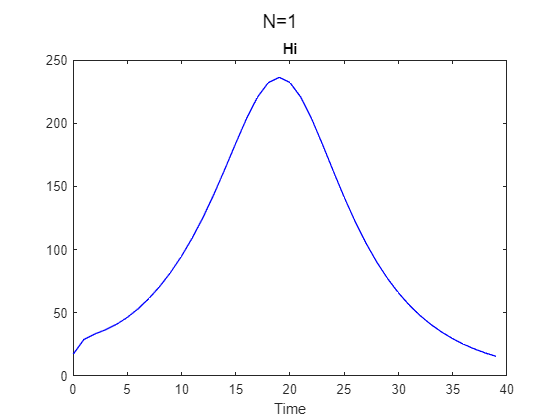

[ydata,xdata]=gsua_eval(T.Nominal,T);

Tia=gsua_likelihood(T,xdata,[],0.95,0.05,1.3,0.5,0.001,100,1,true,false,true,[]);

Estimation 1


Sim100 Done
Sim99 Done
Sim98 Done
Sim97 Done
Sim96 Done
Sim95 Done
Sim94 Done
Sim93 Done
Sim92 Done
Sim91 Done
Sim90 Done
Sim89 Done
Sim88 Done
Sim87 Done
Sim86 Done
Sim85 Done
Sim84 Done
Sim83 Done
Sim82 Done
Sim81 Done
Sim80 Done
Sim79 Done
Sim78 Done
Sim77 Done
Sim76 Done
Sim75 Done
Sim74 Done
Sim73 Done
Sim72 Done
Sim71 Done
Sim70 Done
Sim69 Done
Sim68 Done
Sim67 Done
Sim66 Done
Sim65 Done
Sim64 Done
Sim63 Done
Sim62 Done
Sim61 Done
Sim60 Done
Sim59 Done
Sim58 Done
Sim57 Done
Sim56 Done
Sim55 Done
Sim54 Done
Sim53 Done
Sim52 Done
Sim51 Done
Sim50 Done
Sim49 Done
Sim48 Done
Sim47 Done
Sim46 Done
Sim45 Done
Sim44 Done
Sim43 Done
Sim42 Done
Sim41 Done
Sim40 Done
Sim39 Done
Sim38 Done
Sim37 Done
Sim36 Done
Sim35 Done
Sim34 Done
Sim33 Done
Sim32 Done
Sim31 Done
Sim30 Done
Sim29 Done
Sim28 Done
Sim27 Done
Sim26 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim21 Done
Sim20 Done
Sim19 Done
Sim18 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim14 Done
Sim13 Done
Sim12 Done
Sim11 Done
Sim10 Don

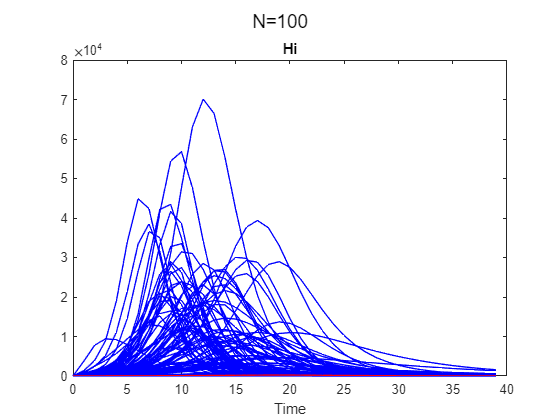

M=gsua_dmatrix(Tia,100);
gsua_eval(M',Tia,xdata,ydata);